# Word2Vec 负采样

Total = 1e9; % 语料总词数
X = 1e6:100:1e9; % 在语料出现的次数

## 抽样率

Z = X./Total;

## 阈值

global SampleRate;
SampleRate = 0.001;

## 保留率

P = (sqrt(Z./SampleRate) + 1).*(SampleRate./Z);

## 绘图

figure(1);
[Z0,fval] = fsolve(@myfun1,0.02);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


[Z05,fval05] = fsolve(@myfun05,0.007);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


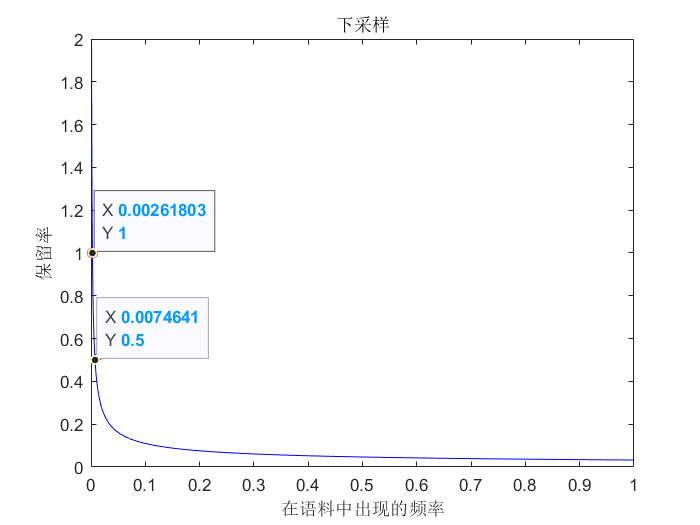

plot(Z, P,'b-',Z0,1,'ro', Z05, 0.5, 'r*');
xlabel('在语料中出现的频率');
ylabel('保留率');
title('下采样');

ax = gca;
chart = ax.Children(1);
datatip(chart,Z0,1);
chart = ax.Children(2);
datatip(chart,Z05,0.5);

## 被选为负采样的概率

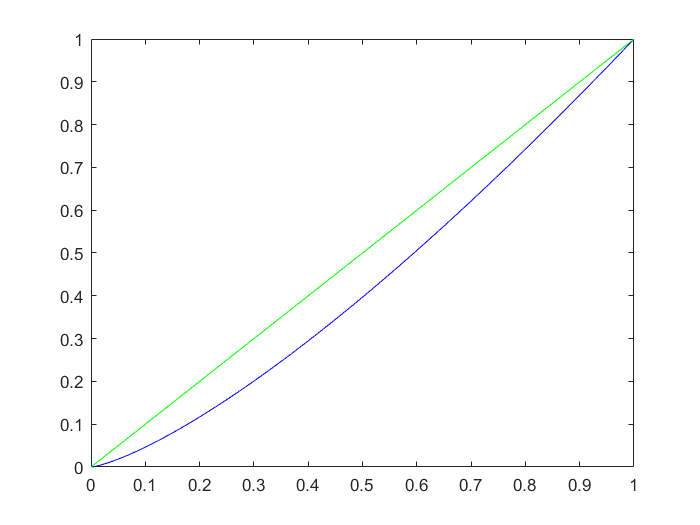

P_N = Z.^(4/3);
figure(2);
plot(Z,P_N,'b-', Z, Z,'g-');

## 函数定义

function P = myfun1(Z)
    global SampleRate;
    P = (sqrt(Z./SampleRate) + 1).*(SampleRate./Z) - 1;
end

function P = myfun05(Z)
    global SampleRate;
    P = (sqrt(Z./SampleRate) + 1).*(SampleRate./Z) - 0.5;
end